# Analytic Reconstruction Modeling

## Nathanael Kazmierczak, 05/30/2020

% analytic_reconstruction_modeling.m
%
% Models the intralayer strain in the absence of a Moire pattern, simply from local Gaussian rotation
% within a planar sheet.
%
% Nathanael Kazmierczak, 05/30/2020
% Bediako Lab, UC Berkeley

syms theta x y
weighted_rot = exp(-x^2-y^2)*theta;
rotmat = [cos(weighted_rot/2), -sin(weighted_rot/2); sin(weighted_rot/2), cos(weighted_rot/2)];
unstrained_layer = [x;y];
strained_layer = rotmat*unstrained_layer;
displacement = strained_layer - unstrained_layer;
x_displacement = displacement(1);
y_displacement = displacement(2);
exx = diff(x_displacement,x);
exy = diff(x_displacement,y);
eyx = diff(y_displacement,x);
eyy = diff(y_displacement,y);
vonMises = exy*eyx - exx*eyy;
gxy = exy + eyx;
torsion = 0.5*(eyx - exy);

gxy_revised = 0.5*(exy + eyx);
fixed_body_rotation = 0.5*(eyx - exy);
vonMises_revised = gxy_revised^2 - exx*eyy;

% This multiplies each x,y position by the rotation value appropriate to that position: namely,
% the gaussian rotation matrix evaluated at x,y. 
%
% Another way of thinking of this: if you ask, "Where did (x0,y0) end up after the rotation 
% process?", you would need to figure out what theta of rotation was used. So you would 
% compute exp(-(x0^2 + y0^2)), and then multiply that by the reconstruction angle and form the
% rotation matrix. This shows that gaussrotmat(x,y)*[x;y] gives the final location of the element
% at [x;y];


## Plot the strain components

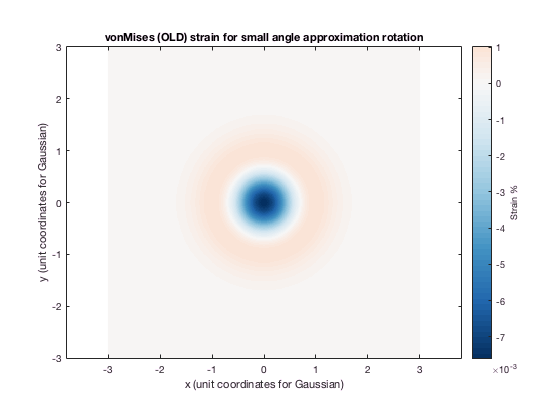

% This section of the workbook added 05/30/2020
load('demo_colormap.mat');
vmfun = matlabFunction(vonMises);
gxyfun = matlabFunction(gxy);
torsionfun = matlabFunction(torsion);
eyxfun = matlabFunction(eyx);
exxfun = matlabFunction(exx);
eyyfun = matlabFunction(eyy);

vmfun_revised = matlabFunction(vonMises_revised);
gxyfun_revised = matlabFunction(gxy_revised);

limval = 3;
xbase = -limval:0.01:limval;
ybase = -limval:0.01:limval;
[xspace,yspace] = meshgrid(xbase,ybase);

figure;
vmres = vmfun(deg2rad(1.0),xspace,yspace);
imagesc(xbase,ybase,vmres*100); axis equal; set(gca,'yDir','normal'); cbh = colorbar; scaleColorMap(cmap,0);
title('vonMises (OLD) strain for small angle approximation rotation');
xlabel('x (unit coordinates for Gaussian)');
ylabel('y (unit coordinates for Gaussian)');
ylabel(cbh,'Strain %');


figure;
vmrevres = vmfun_revised(deg2rad(1.0),xspace,yspace);
imagesc(xbase,ybase,vmrevres*100); axis equal; set(gca,'yDir','normal'); cbh = colorbar; scaleColorMap(cmap,0);

Error using image
Invalid datatype for Image CData. Numeric or logical matrix required for image CData.

Error in imagesc (line 20)
    hh = image(varargin{:},'CDataMapping','scaled');

title('vonMises (new) strain, fixed body rotation removed');
xlabel('x (unit coordinates for Gaussian)');
ylabel('y (unit coordinates for Gaussian)');
ylabel(cbh,'Strain %');

figure
gxyres = gxyfun(deg2rad(1.0),xspace,yspace);
imagesc(xbase,ybase,gxyres*100); axis equal; set(gca,'yDir','normal'); cbh = colorbar; scaleColorMap(cmap,0);
title('Total shear strain (gxy, OLD) for small angle approximation rotation');
xlabel('x (unit coordinates for Gaussian)');
ylabel('y (unit coordinates for Gaussian)');
ylabel(cbh,'Strain %');

figure
gxyrevres = gxyfun_revised(deg2rad(1.0),xspace,yspace);
imagesc(xbase,ybase,gxyrevres*100); axis equal; set(gca,'yDir','normal'); cbh = colorbar; scaleColorMap(cmap,0);
title('Pure shear strain (gxy, new) for small angle approximation rotation');
xlabel('x (unit coordinates for Gaussian)');
ylabel('y (unit coordinates for Gaussian)');
ylabel(cbh,'Strain %');

figure
torsionres = torsionfun(deg2rad(1.0),xspace,yspace);
imagesc(xbase,ybase,rad2deg(torsionres)); axis equal; set(gca,'yDir','normal'); cbh = colorbar; scaleColorMap(cmap,0);
title('Fixed body rotation for small angle approximation');
xlabel('x (unit coordinates for Gaussian)');
ylabel('y (unit coordinates for Gaussian)');
ylabel(cbh,'Rotation angle (deg)');

figure
exxres = exxfun(deg2rad(1.0),xspace,yspace);
imagesc(xbase,ybase,exxres*100); axis equal; set(gca,'yDir','normal'); cbh = colorbar; scaleColorMap(cmap,0);
title('exx normal strain');
xlabel('x (unit coordinates for Gaussian)');
ylabel('y (unit coordinates for Gaussian)');
ylabel(cbh,'Strain %');

figure
eyyres = eyyfun(deg2rad(1.0),xspace,yspace);
imagesc(xbase,ybase,eyyres*100); axis equal; set(gca,'yDir','normal'); cbh = colorbar; scaleColorMap(cmap,0);
title('eyy normal strain');
xlabel('x (unit coordinates for Gaussian)');
ylabel('y (unit coordinates for Gaussian)');
ylabel(cbh,'Strain %');
